# Euler-Bernoulli beam (steady-state, 1d)

Nb = 4;
gauss_points_num = 8;
master = [0 1];
Npts = 100; % for plotting

% hermite cubic polynomials
coeffs = [1,0,-3,2; 
    0,1,-2,1;
    0,0,3,-2;
    0,0,-1,1];
L_const = 254;

s_const = 76.2;
sigma0_const = 1e6;
E_const = 20.7e9;
I_const = 249739;
d_const = 4.572*100;
c_const = 0.03;

A_const = s_const*sigma0_const;

B_const = log(10)/(c_const*d_const);
K_const = A_const/(E_const*I_const);

L = L_const;
NEL = 10;

% basis functions on the master element
N = basis_functions(coeffs);
d2_N = basis_derivatives(coeffs, 2);
d3_N = basis_derivatives(coeffs, 3);

% global nodes
xs = linspace(0,L,NEL+1);

% mesh sizes
hs = zeros(NEL,1);
for i=1:NEL
    hs(i) = xs(i+1) - xs(i);
end

% element nodes
es = zeros(NEL,2);
for i=1:NEL
    es(i,:) = [xs(i) xs(i+1)];
end

% local stiffness and mass matrices
Kl = zeros(Nb,Nb,NEL);
Ml = zeros(Nb,Nb,NEL);
for k=1:NEL
    for i=1:Nb
        for j=1:Nb
            Kl(i,j,k) = 1 / (hs(k))^3 * gauss(@(x) d2_N(i,x) * d2_N(j,x), master(1), master(2), gauss_points_num);
            Ml(i,j,k) =      hs(k)    * gauss(@(x)    N(i,x) *    N(j,x), master(1), master(2), gauss_points_num);
        end
    end
end

% Global matrices and force term
Kn = (NEL+1)*2;
K = zeros(Kn,Kn); M = zeros(Kn,Kn);

for i=1:NEL
    K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = K(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Kl(1:Nb,1:Nb,i);
    M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) = M(2*i-1:2*i+Nb-2,2*i-1:2*i+Nb-2) + Ml(1:Nb,1:Nb,i);
end
 
% Use fixed point iteration for u
% Start with the initial guess
us = zeros(length(K),1);
niter = 50;
for i=1:niter
    force = K_const*construct_f(us,NEL,Nb,hs,master,gauss_points_num,N,B_const);
    us(3:end) = K(3:end,3:end)\force(3:end);
end

% local u coefficients
u_locals = zeros(NEL, Nb);
for i=1:NEL
    u_locals(i,1:end) = us(2*i-1: 2*i+Nb-2);
end

% producing piecewise polynomial approximation
xxxs = linspace(0,L,Npts);
u_vals = zeros(length(xxxs),1);
for i=1:length(xxxs)
    u_vals(i) = u_fun(u_locals, xxxs(i), NEL, Nb, N, es, xs);
end

## Plotting

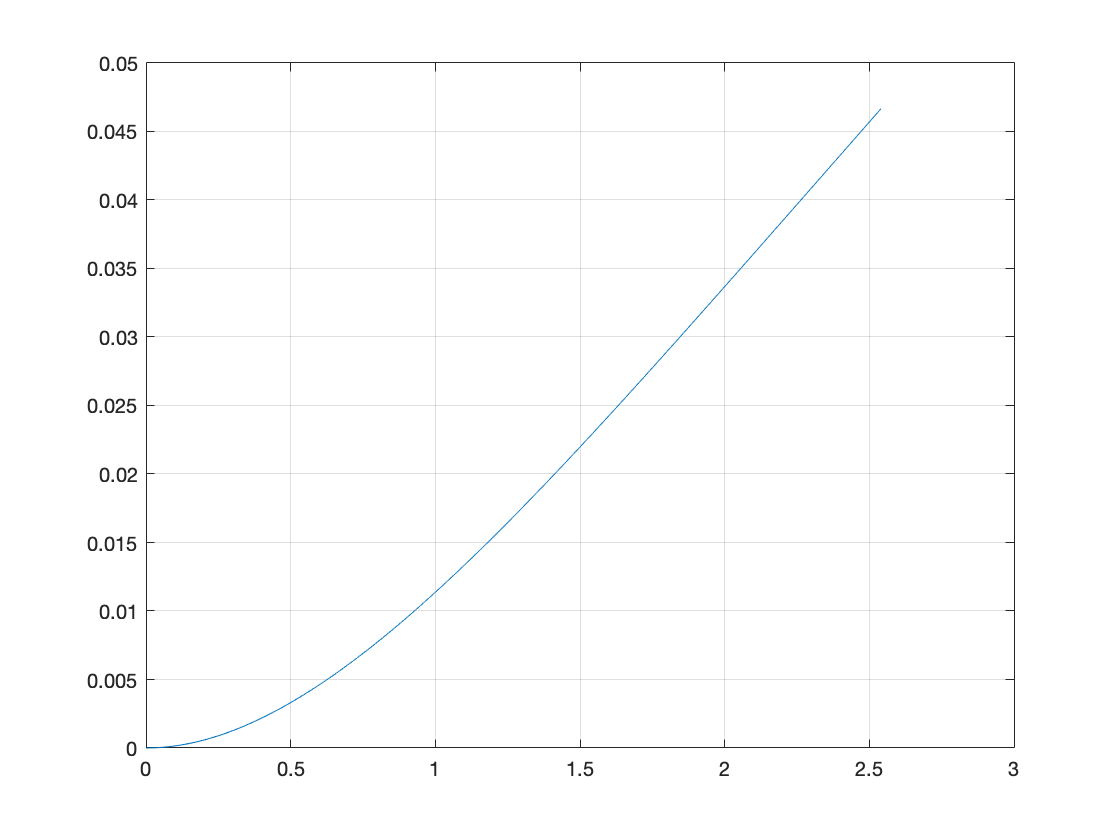

plot(xxxs/100,u_vals/100)
grid on

## FEM tools

function res = exp(x,B_const)
    res = 1 + (-B_const*x) + (-B_const*x)^2/2 + (-B_const*x)^3/6 + (-B_const*x)^4/24;
end

function res = chi(e,x,xs) 
    res = false;
    if x > xs(e) && x <= xs(e+1)
        res = true;
    end
end

function res = xi(x,xe)
    res = (x - xe(1)) / (xe(2) - xe(1));
end

function res = get_u(u,xi,N)
    res = u(1)*N(1,xi) + u(2)*N(2,xi) + u(3)*N(3,xi) + u(4)*N(4,xi);
end

function f_global = construct_f(us,NEL,Nb,hs,master,gauss_points_num,N,B_const)
    u_local = zeros(NEL, Nb);
    for i=1:NEL
        u_local(i,:) = us(2*i-1:2*i+Nb-2);
    end
        
    f_local = zeros(NEL,Nb);
    for i=1:NEL
        for j=1:4
            f_local(i,j) = hs(i)*gauss(@(x) N(j,x) * exp(get_u(u_local(i,:),x,N),B_const), master(1), master(2), gauss_points_num);
        end
    end
    
    f_global = zeros(length(us),1);
    for i=1:NEL
        f_global(2*i-1:2*i+Nb-2) = f_global(2*i-1:2*i+Nb-2) + f_local(i,1:Nb)';
    end
end

% assemble u(x) from u_i coefficients
function res = u_fun(u_locals, x, NEL, Nb, N, es, xs)
    res = 0;
    for i=1:NEL
        sm = 0;
        for j=1:Nb
            sm = sm + u_locals(i,j) * N(j,xi(x,es(i,:)));
        end
        sm = sm * chi(i,x,xs);
        res = res + sm;
    end
end

function q = get_q(u_locals, es, d2_N, d3_N)
    q = zeros(2);
    e = 0;
    for j=1:Nb
        q(1) = q(1) + u_locals(e,j) * d2_N(j,xi(1,es(e)));
        q(2) = q(2) + u_locals(e,j) * d3_N(j,xi(1,es(e)));
    end
    q = q/100;
end

## Polynomial tools

function basis = basis_functions(coefficient_matrix)
    mat_size = length(coefficient_matrix);
    basis = @(index, x) coefficient_matrix(index,1:mat_size)*(x.^(0:mat_size-1))';
end

function der_mat = derivative_matrix(basis_order, derivative_order)
    der_mat = zeros(basis_order, basis_order);
    for i=derivative_order+1:basis_order
        prod = 1;
        for j=1:derivative_order
            prod = prod*(i-j);
        end
        der_mat(i-derivative_order,i) = prod;
    end
    der_mat = sparse(der_mat');
end

function res = basis_derivatives(coefficient_matrix, order)
    der_mat = derivative_matrix(length(coefficient_matrix), order);
    res = basis_functions(coefficient_matrix*der_mat);
end

function res = gauss(fun, a, b, order)
    [x,w] = lgwt(order,a,b);
    f = arrayfun(fun,x);
    res = sum(f.*w);
end